# Implémentation du filtre de KALMAN pour la position des trains

## I/ Introduction et objectif

3 trains (EVC) parcourent des circuits différents sur la maquette UNIRAIL de Centrale Lille. Ils partagent cependant des aiguillages et tronçons (découpage du réseau ferré) en commun, ce qui impose la présence d'un gestionnaire au sol, qui , par la connaissaince de la position de chaque train sur leur tronçon courant, ainsi que le tronçoon courant, leur alloue l'accés à ces ressources critiques afin d'éviter les collisions et les blocages. Cet ordinateur au sol, appelé RBC, doit donc recevoir une information sur cette positon précise et fiable. Nous disposons pour cela de deux capteurs de positon par EVC : un codeur incrémental, qui, par odométrie, donne la distance parcourue depuis l'instant initial, pouvant être actualisé lors du passage du train au dessus des balises présentes dans l'infrastucture du réseau ferré, ainsi que sa vitesse, et un récepteur marvelmind, simulant le GPS, qui fournir les coordonnées du train dans le repère des marvelminds de la salle UNIRAIL ( 4 marvelminds étant situés au 4 coins de la maquette). 

Afin d'augmenter la fiabilité des données en exploitant ces deux capteurs, nous décidons d'implémenter un filtre de Kalman qui réduira l'incertitude concernant la position du train sur son tronçon. Dans un premier temps, des étapes de traitement des données doivent être implémentées. Nous développons ensuite une fonction de filtrage de Kalman. Enfin, nous combinons ces deux parties pour avoir un algorithme complet. 

Il s'agit là d'une étape de développement, une fois les paramètres déterminés et cette étape validée, nous implémenterons ces fonctions dans les bibliothèques C dédiées.  

Ts = 18*10^-3; %période d'échantillonnage
F_marv = 8; %Hz, fréquence du marvelmind
v_max = 45; %cm.s^-1 vitesse max des trains sur le circuit
margins = 0.2; %marges prises

% Assigning the path
path = 'C:\Users\Utilisateur\OneDrive - Cranfield University\Desktop\François\scolarité\Centrale_sco\S_9\UNIRAIL\data_estimation'; %abc is your folder which contains the txt file
% Assigning a variable to access the file
fileName_1 = [path,'\data_1.txt'];
fileName_2 = [path,'\tour_odometrie.txt'];
% Importing all the data from the txt file
fileEntireDataSet_1 = importdata(fileName_1);
fileEntireDataSet_2 = importdata(fileName_2);
% Assigning the first column only
velocities_1 = fileEntireDataSet_1(:,2);
pos_1 = fileEntireDataSet_1(:,1);
time_1 = fileEntireDataSet_1(:,3);

velocities_2 = fileEntireDataSet_2(:,2);
pos_2 = fileEntireDataSet_2(:,1);
time_2 = 10*fileEntireDataSet_2(:,3);
size_est_2 = 300;
t_2_final = 10*fileEntireDataSet_2(size_est_2,3);
interval_2 = t_2_final/size_est_2;
time_2_corrected = zeros(size_est_2,1);
velocities_2_corrected = zeros(size_est_2,1);
time_2_corrected(1,1)=time_2(1);
velocities_2_corrected(1,1)=velocities_2(1);
for i = 2:size_est_2
    time_2_corrected(i,1)=time_2_corrected(i-1,1)+interval_2;
    velocities_2_corrected(i,1)=velocities_2(i);
end

windowSize = 6; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;
velocities_2_filtered = filter(b,a,velocities_2_corrected);

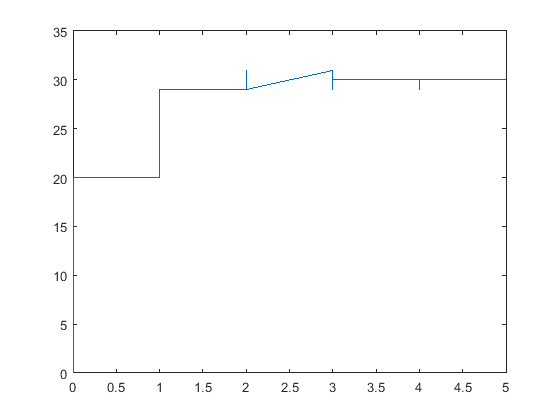

plot(time_1,velocities_1);

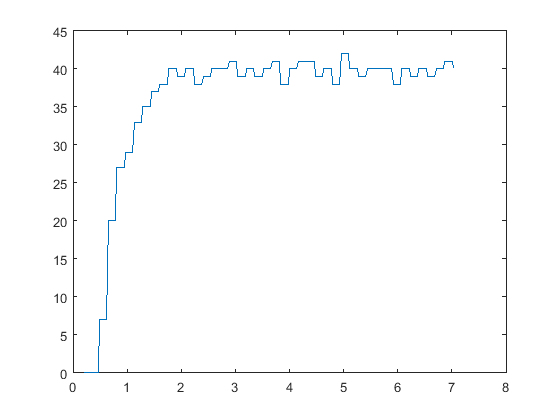

plot(time_2_corrected,velocities_2_corrected);

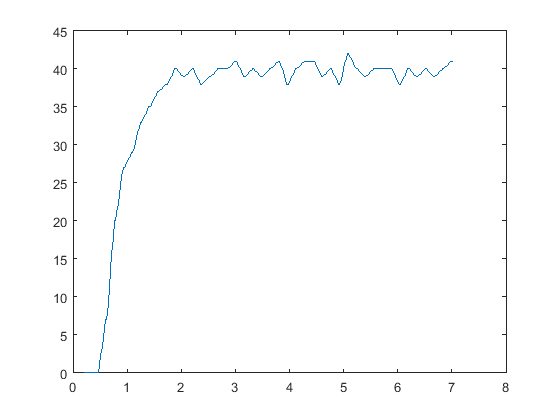

plot(time_2_corrected,velocities_2_filtered);

## tfest etimation

Dans un premier temps, nous devons récupérer la consigne en fonction du temps. Pour cela, nous créons un modèle simulink nommé commande_30 qui génère la consigne souhaitée à l'instant souhaité pour cette première analyse de la réponse temporelle du système. 

sim('commande_30.slx',4.95); % most basic way to simulate with command script.

command_2 = zeros(size_est_2,1);
for i = 10:size_est_2
    command_2(i,1)=40;
end


DAT_1 = iddata(velocities_1,ans.consigne_v,1/39);
sys_1 = tfest(DAT_1,2,0)

sys_1 =
 
  From input "u1" to output "y1":
              
         18.11
              
  --------------------
                      
  s^2 + 10.42 s       
                      
               + 18.11
                      
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "DAT_1".
Fit to estimation data: 90.77%                    
FPE: 0.8423, MSE: 0.8                             


DAT_2 = iddata(velocities_2_corrected,command_2,interval_2);
sys_2 = tfest(DAT_2,2,0)

sys_2 =
 
  From input "u1" to output "y1":
              
         62.11
              
  --------------------
                      
  s^2 + 27.43 s       
                      
               + 62.39
                      
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "DAT_2".
Fit to estimation data: 87.48%                    
FPE: 1.495, MSE: 1.446                            


DAT_3 = iddata(velocities_2_filtered,command_2,interval_2);
sys_3 = tfest(DAT_3,2,0)

sys_3 =
 
  From input "u1" to output "y1":
              
         26.28
              
  --------------------
                      
  s^2 + 12.87 s       
                      
               + 26.41
                      
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "DAT_3".
Fit to estimation data: 92.05%                    
FPE: 0.6643, MSE: 0.6425                          


k_1 = sys_1.Numerator;
w_n_1 = sqrt(sys_1.Denominator(3));
xsi_1 = 1/(2*w_n_1)*sys_1.Denominator(2);

k_2 = sys_2.Numerator;
w_n_2 = sqrt(sys_2.Denominator(3));
xsi_2 = 1/(2*w_n_2)*sys_2.Denominator(2);

k_3 = sys_3.Numerator;
w_n_3 = sqrt(sys_3.Denominator(3));
xsi_3 = 1/(2*w_n_3)*sys_3.Denominator(2);

%step(sys)

%Définition des matrices du modèle continu Ac ; Bc

Ac = [0 1; -w_n^2 -2*xsi*w_n];
Bc = [0; w_n^2*k];
Cc = eye(2);
Dc = 0;
sys_c = ss(Ac,Bc,Cc,Dc);
sys_d = c2d(sys_c,Ts);

## Données marvelmind preprocessing

m = readtable('marvelmind_1.txt');

X_marv = string(m.Var4);
Y_marv = string(m.Var6);
Z_marv = string(m.Var8);
time_marv = string(m.Var16);

## Création des tableaux X,Y,Z et time

X_marv_num = zeros(526,1);
Y_marv_num = zeros(526,1);
Z_marv_num = zeros(526,1);
time_marv_num = zeros(526,1);
n = length(X_marv);

for i = 1:length(X_marv)
 
    X_marv_str_i = strsplit(X_marv(i),',');
    X_marv_num_i = str2num(X_marv_str_i(1));

    Y_marv_str_i = strsplit(Y_marv(i),',');
    Y_marv_num_i = str2num(Y_marv_str_i(1));

    Z_marv_str_i = strsplit(Z_marv(i),',');
    Z_marv_num_i = str2num(Z_marv_str_i(1));

    time_marv_str_i = strsplit(time_marv(i),',');
    time_marv_num_i = str2num(time_marv_str_i(1));

    X_marv_num(i) = X_marv_num_i;
    Y_marv_num(i) = Y_marv_num_i;
    Z_marv_num(i) = Z_marv_num_i;
    time_marv_num(i) = time_marv_num_i;
end

t_0 = time_marv_num(1,1);

## Plot de la trajectoire

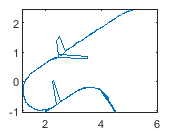

plot(X_marv_num,Y_marv_num);

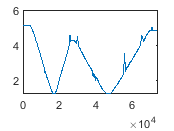

plot(time_marv_num-t_0,X_marv_num);

## Première étape de post-processing : suppression des valeurs abhérantes 

On voit sur le tracé de la trajectoire du train relevée par les marvelminds que des données erronnées sont relevées et doivent être supprimées afin d'avoir des données en position en sortie du filtre de Kalman, après fusion avec les données odométriques, fiables. 

On choisit une variation autorisée pour les valeurs en X et Y de 10% par rapport à la donnée précédente. Ainsi, si ces deux valeurs dépssent simultanément ce seuil, on reprend la valeur précédente à laquelle on ajoute la vitesse * T où T est la période d'échantillonnage du Marvelmind. 

### Analyse des données

#### Cas de X_marv

X_marv_var = zeros(526,1)';
rank = linspace(1,526,526);

for i = 2:(length(X_marv_var))
    var =(X_marv_num(i)-X_marv_num(i-1))/X_marv_num(i)*100;
    if abs(var) > 10
        X_marv_var(i)=var;
        disp(i);
    else
        X_marv_var(i) = 0;
    end
end

   184

   217

   274

   284

   398

   402

   465



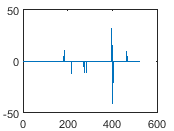

plot(rank,X_marv_var);

#### Cas de Y_marv

Y_marv_var = zeros(525,1);

for i = 2:(length(Y_marv_var))
    var =(Y_marv_num(i)-Y_marv_num(i-1))/Y_marv_num(i)*100;
    if abs(var) > 10
        Y_marv_var(i)=var;
        disp(i);
    else
        Y_marv_var(i) = 0;
    end
end

    85

    89

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125

   126

   170

   182

   184

   188

   213

   217

   219

   274

   275

   276

   278

   279

   283

   284

   288

   338

   339

   340

   341

   342

   343

   344

   345

   346

   347

   348

   349

   350

   351

   352

   353

   354

   355

   356

   357

   358

   465



#### Cas de Z_marv

Z_marv_var = zeros(525,1);

for i = 2:(length(Z_marv_var))
    var =(Z_marv_num(i)-Z_marv_num(i-1))/Z_marv_num(i)*100;
    if abs(var) > 10
        Z_marv_var(i)=var;
        disp(i);
    else
        Z_marv_var(i) = 0;
    end
end

   398

   402

   465

   473



### Mise en place de l'algorithme

Ici, on développe sous Matlab l'algorithme que l'on exporte en C par la suite pour le ranger comme fonction dans la librairie train.c puisque ces traitements de données sont réalisés à bord de l'EVC.

Voici le schéma explicatif de cette fonction. On voit qu'elle prend en arguments le **vecteur vitesse** calculé à chaque instant **en sortie de Kalman**, **exprimée dans le repère des Marvelminds**, qui est donc une donnée fiable. Il faudra développer cette fonction également. 

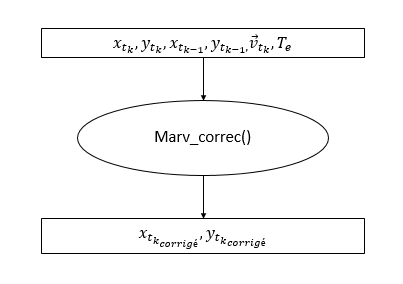

Exemple d'utilisation de la fonction marv_correc().m:

x_t_k = X_marv_num(301);
y_t_k = Y_marv_num(301);
x_t_k_minus = X_marv_num(300);
y_t_k_minus = Y_marv_num(300);
T_e_marv = 1/8; %%8Hz
v_x = 4; %arbitrary
v_y = -2;%arbitrary
marv_correc(x_t_k,y_t_k,x_t_k_minus,y_t_k_minus,T_e_marv,v_x,v_y);

    1.8100

   -0.9830



## Deuxième étape de pré-processing : calcul de la distance parcourue

L'objectif de cette fonction est de calculer la distance parcourue sur les rails dans un canton c_i. Il faut pour cela connaître les coordonnées des c_i dans le repère des marvelminds. L'odométrie fournit la distance parcourue en cm depuis le début du tronçon (si on actualise avec les balises,ce qui est pour le moment l'option privilégiée en dépit de l'incertitude sur le moment ù l'actualisation est établie), il nous faut donc fournir cette donnée par les marvelminds. 

dist_parc_marv = 20;


dist_marv = calc_dist_marv(dist_parc_marv, x_t_k,y_t_k,x_t_k_minus,y_t_k_minus);

    0.0182



## Troisième étape: Positionnement des tronçons

Nous n'actualisons pas les données marvelminds avec les balises lors de l'entrée dans les tronçons. Au lieu de cela, nous utilisons la localisation exacte des tronçons que nous passons dans le repère marvelmind. Lorsque cela est fait, nous comparons les coordonnées du train en sortie de marvelmind à ces positions, et actualisons dist_parc à 0 lorsque l'on se trouve dans un cercle de rayon 3.4 cm (à vérifier) du canton. On prend 20% de marge. 

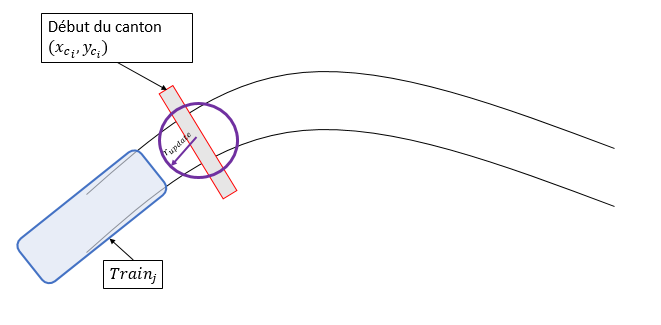

8Hz à (vitesse_max = 45 cm.s^-1) :

dist_worst_case_marvel = 1/F_marv*v_max; %cm
radius_update = dist_worst_case_marvel*(1+margins)/2; %cm

On pourrait penser à utiliser la liste complète des coordonnées des balises de chaque canton. Toutefois, il semble plus logique que le train ne se concentre que sur le "prochain" canton qu'il connaît, puisqu'il connaît son parcourt, et ne fait pas de marche arrière. 

## Mise en place du filtre de Kalman

### 1/ Basé sur la cinématique

A faire

### 2/Basé sur la dynamique

La matrice H du modèle de mesure est obtenue en prenant en compte le fait que l'on mesure la distance parcourue ainsi que la vitesse directement avec l'odométrie, mais seulement la distance parcourue, et ce indirectement, avec les marvelminds. On développe la fonction Kalman_dyn sur cette base (cf slides du cours). On a donc: 

H = [1 0; 1 1];

## Création de la fonction complète

Les fonctions nécessaires à l'implémentation du filtre de Kalman embarqué ont été développées et détaillées au-dessus. Il faut maintenant construire une fonction générale qui fait appel à ces sous-fonctions et permet, en sortie, d'obtenir à chaque instant échantillonné, une donnée fiable de la position de train i sur le tronçon courant. Cette information sera alors transmise à une fonction d'envoie des données de position de l'EVC (train i) vers le RBC (Raspberry au sol, qui donne les autorisations de mouvement). 